datastore = CLIPDatastore(ImageFolder="./flickr-dataset/Flicker8k_Dataset");
ds = shuffle(datastore)

ds =   CLIPDatastore with no properties.


[net,tokenizer] = bert();

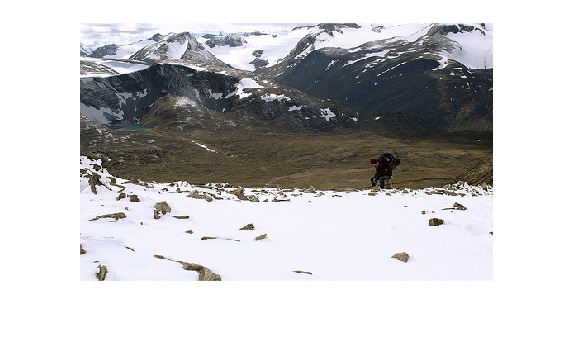

[im, tokens, caption] = read(ds);
imshow(im)

%caption = "A group of horse and their rider be race each other .";
[~, segments] = encode(tokenizer, caption);

dltoken = dlarray(tokens, 'CT');
dlsegment = dlarray(segments{1}, 'CT');
mask = dlarray(ones(1, numel(dlsegment)), 'CT');

pred = predict(net, dltoken, mask, dlsegment);

decodedTokens = decode(tokenizer, tokens)

decodedTokens = "[CLS] a lone hiker be sit on a rock on a snowy mountain trail . [SEP]"

disp(size(pred))

   768    17



last = pred(:,1) % Use the [CLS] token

last =   768(C) × 1(T) single dlarray

   -0.4155
    0.1214
    0.0106
    0.1995
    0.1726
   -0.3320
   -0.6836
   -0.7748
    0.4483
   -0.4697
   -1.1779
    0.7522
    0.1292
    0.1734
    0.3057
   -0.3118
    0.3762
    0.3930
   -0.1571
   -0.3242
    0.4645
    0.0175
    0.5672
   -0.1293
    0.6099
   -0.0865
   -0.4777
   -0.5859
    0.4983
    0.4126
    0.3799
   -0.3088
   -1.0851
   -0.0679
    0.4004
    0.0723
    0.1086
    0.8775
    0.0182
   -0.6249
   -0.2228
   -0.8301
    0.2281
   -0.4656
   -0.1623
   -0.2075
    0.1600
    0.9947
   -0.5264
    0.2698
   -0.0178
    0.3690
    0.1942
   -0.2170
   -0.2707
    0.5441
    0.9365
   -0.2250
   -0.1440
   -0.2589
    0.3005
   -0.0683
    0.4084
   -0.7231
    0.1576
    0.4412
    0.1242
    0.0647
    0.4512
    0.5335
    0.0857
   -0.0523
   -0.9395
    0.1275
   -0.2231
   

% NB: Using Bert for batched prediction
[net, tokenizer] = bert("Model","tiny");
paddingValue = tokenizer.PaddingCode;
str = [
    "Coolant is pooling underneath sorter."
    "Sorter blows fuses at start up."
    "There are some very loud rattling sounds coming from the assembler."];
[inputIdsStr, segmentIdsStr] = encode(tokenizer, str);

% The `maskStr` is used to specify the indices of the `paddingValue` so
% that the model ignores the padding
[inputIdsStr, maskStr] = padsequences(inputIdsStr, 2,"PaddingValue",paddingValue);
segmentIdsStr = padsequences(segmentIdsStr, 2,"PaddingValue",paddingValue);

inputIdsStr = dlarray(inputIdsStr, "CTB");
maskStr = dlarray(maskStr, "CTB");
segmentIdsStr = dlarray(segmentIdsStr, "CTB");

predictions = predict(net,inputIdsStr,maskStr,segmentIdsStr);

net = imageEncoder();
randX = dlarray(randn(net.Layers(1).InputSize), 'SSC');
net = dlnetwork(imEncoder, randX);
out = predict(net, randX);
disp(size(out))

           1           1        2048



net = textEncoder();
randX = dlarray(randn(1,1,10), 'CBT');
net = dlnetwork(net, Initialize=false);
net = initialize(net, randX, randX, randX)

net =   dlnetwork with properties:

         Layers: [1×1 nnet.cnn.layer.NetworkLayer]
    Connections: [0×2 table]
     Learnables: [197×3 table]
          State: [0×3 table]
     InputNames: {'subnet/input_ids'  'subnet/attention_mask'  'subnet/seg_ids'}
    OutputNames: {'subnet'}
    Initialized: 1

  View summary with summary.



randInputIDs = dlarray(randi(1000, [1 3 10]), 'CBT');
attentionMask = dlarray(ones(size(randInputIDs)), 'CBT');
segmentIDs = dlarray(ones(size(randInputIDs)), 'CBT');

out = predict(net, randInputIDs, attentionMask, segmentIDs);
clsEmbeddings = out(:,:,1);